# EECI Graduate School: Learning-Based Predictive Control

Lukas Hewing, Alexandre Didier, Jérôme Sieber

***Copyright (C) 2020, ETH Zurich, {lhewing, jsieber, adidier}@ethz.ch***

**This code is only made available for students taking the EECI Learning-Based Predictive Control graduate school and is NOT to be distributed.**

**Requires MPT Toolbox: https://www.mpt3.org/**

## Robust Learning-Based MPC of Mass-Spring-Damper

### `Preliminaries`

You are provided with the following coding template files: 

- `E02_RobustLBMPC.mlx     `Main (live) script

- `SetMembership.m        `  Set memberhip estimation class

- `PLMPC.m                 `Performance learning MPC class

- `SMMPC.m                 `Set Membership MPC class

- `RobustMPC.m             `Robust MPC class (Solution from E01)

- `RobustMPC.mat      `          Robust MPC instance (Solution from E01)

- `LinearSystem.m          `Helper Class

- `SimulateMSD.m           `Helper Function

Areas in the code to be modified are indicated by 


% --------- Start Modifying Code Here -----------
%
% The existing (incomplete) code in the modifiable areas serves as a hint
%
% --------- End Modifying Code Here -----------


Clean up script

clear
close all

% fix random seed
rng(3)

### Problem Description

In this exercise we investigate performance learning and set-membership (adaptive) robust linear MPC for the simple mass-spring damper system of Exercise 1. Different to the first exercise, we now consider a mismatch between the true system 


$$x(k\!+\!1) = A_{\text{true}} x(k) + B_{\text{true}} u(k) + w(k),  \quad A_{\text{true}} =  \left[ \matrix{ 1 & T_s \cr -k_{\text{true}} T_s & 1-d_{\text{true}} T_s } \right],  \ B_{\text{true}} = \left[\matrix{ 0 \cr T_s }\right]$$


and the nominal model used in the MPC


$$x_{i+1} = A x_i + B u_i + w_i,\quad A =  \left[ \matrix{ 1 & T_s \cr -k T_s & 1-d T_s } \right],  \ B = \left[\matrix{ 0 \cr T_s }\right]$$


We assume $-0.01 \leq \Delta k = k_{\text{true}} - k \leq 0.01$ and $-0.1 \leq \Delta d = d_{\text{true}} - d \leq 0.1
$.

**System Definition**

The cells below to define the mass spring damper model. Differnt to the previous exercis, we now consider a mismatch between model and real system:

% ==============
% System Parameters
% ==============

% Discretization time
Ts=0.25;

% Nominal system
% Spring and damper constant
k_nom=0.3;
d_nom=0.2;

% Continuous time model:
Ac_nom = [0, 1; -k_nom -d_nom];
Bc_nom = [0; 1];

% Discretized system
A_nom = eye(2) + Ts*Ac_nom;
B_nom = Ts*Bc_nom;

% True system
dk_max = 0.01; %maximum spring constant deviation from nominal
dd_max = 0.1; %maximum damping constant deviation from nominal

% Spring and damper constant (use worst case deviation)
k_true=k_nom - dk_max;
d_true=d_nom + dd_max;

% Continuous time model:
Ac_true = [0, 1; -k_true -d_true];
Bc_true = [0; 1];

% Discretized system
%[A_true, B_true] = c2d(Ac_true,Bc_true,Ts);
A_true = eye(2) + Ts*Ac_true;
B_true = Ts*Bc_true;

% ==============
% System Constraints
% ==============

% State constraints; Hx*x <= bx
Hx=[1,0; 0, 1; -1,0; 0, -1];
bx=[1; 1; 5; 1];

% Input constraints; Hu*u <= bu
Hu=[1;-1];
bu=[1;1];

% Instantiate Systems
sys_true = LinearSystem(A_true, B_true, Hx, bx, Hu, bu);
sys = LinearSystem(A_nom, B_nom, Hx, bx, Hu, bu);

### **I. Recap Robust MPC**

We first investigate the robust MPC solution of Exercise 1 for this modified system. Note that robust guarantees designed for additive disturbances $w \in \mathcal{W}$ hold as long as


$$x(k\!+\!1) - Ax(k) - Bu(k) \in \mathcal{W}$$


where the controller designed was robust for $\mathcal{W} = \{ Bw \, | \, |w| \leq 0.2\}$

Now we consider two sources of uncertainty: One is due to the model mismatch described previously, and the other are additional unmodeled disturbances $$w(k) \in \bar{\mathcal{W}} := \{ Bw \, | \, |w| \leq \bar{w}\}$$. Your task is now to compute the maximum $$\bar{w}$$ for which


$$x(k\!+\!1) - Ax(k) - Bu(k) + w(k) \in \mathcal{W}$$


for all $x(k) \in \mathcal{X}$ and $u(k) \in \mathcal{U}$, i.e. how large the unstructured disturbance $w(k)$can be on top of the model mismatch such that the original robust guarantees apply.

*Hint: Note that both disturbance and model error only affect the second state i.e. the velocity. *

% compute maximum absolute value error due to model mismatch on sys.Px


w_theta_k_max_c = 0.0500

% --------- Start Modifying Code Here -----------

w_theta_k_min_c = -0.0500

% % Error due to spring constrant
w_theta_k_max_c = -dk_max*sys.xmin(1)   % max value that delta_k * x_1 can take
w_theta_k_min_c = dk_max*sys.xmin(1)    % min value that delta_k * x_1 can take
w_theta_k_max = Ts*w_theta_k_max_c;   % due to discretization
w_theta_k_min = Ts*w_theta_k_min_c;   % due to discretization

% % Error due to damping constrant
w_theta_d_max_c = dd_max*sys.xmax(2);   % max value that delta_d * x_2 can take
w_theta_d_min_c = -dd_max*sys.xmax(2);  % min value that delta_d * x_2 can take
w_theta_d_max = Ts*w_theta_d_max_c;   % due to discretization
w_theta_d_min = Ts*w_theta_d_min_c;   % due to discretization

% --------- Stop Modifying Code Here ------------

% total maximum error
w_theta_max = w_theta_k_max + w_theta_d_max;
w_theta_min = w_theta_k_min + w_theta_d_min;

% maximum absolute value error
w_theta_abs = max(abs(w_theta_max),abs(w_theta_min));

w_max = 0.0500


% recompute (symmetric w_max)
w_max = 0.2 - w_theta_abs/sys.B(2)

Load yesterday's robust MPC solution `RobustMPC.mat` and simulate the system with the robust MPC and adjusted noise level by drawing $w(k)$ uniformly from $$\bar{\mathcal{W}}$$. What do you notice?  (repeat simulations for different disturbance realizations)

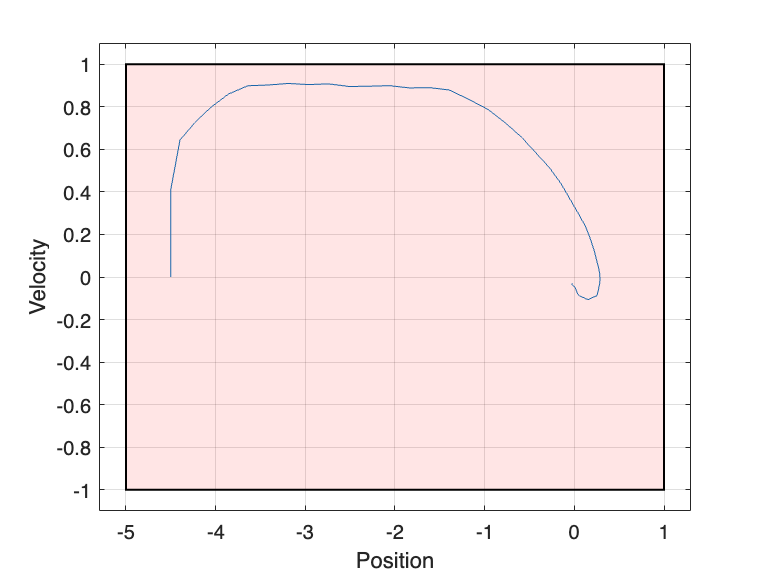

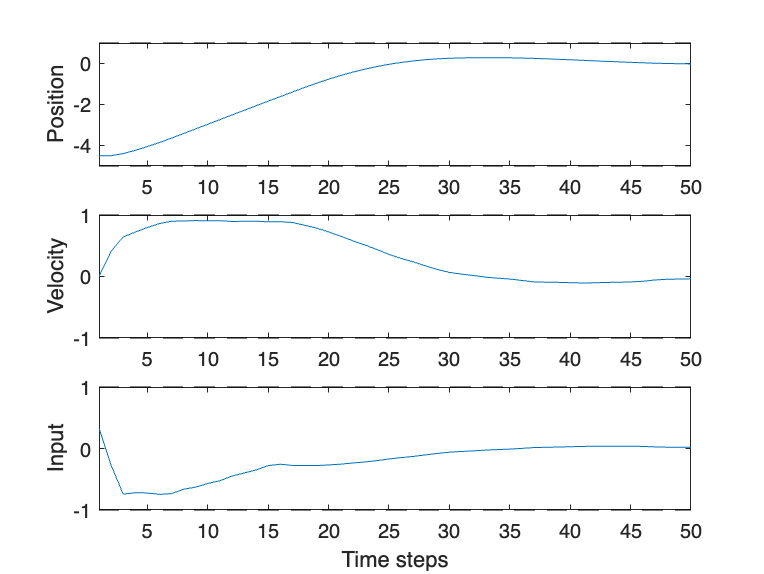

load('robustMpc')

% ==============
% Simulate System
% ==============

% Initial condition
x_init=[-4.5;0];

% Number of time steps in each simulated trajectory
T = 50;

% Define Controller function
pi_r = @(x) robustMpc.solve(x);

% consider additional uniform random disturbances
w = sys.B*(rand(1,T)*2*w_max -w_max);


% Simulate system
[x, u] = SimulateMSD(sys_true,pi_r,x_init,T,w);


Jrobust = 258.8125

% Evaluate closed-loop cost
Jrobust = sum(sum(x.*(robustMpc.Q*x))) + sum(sum(u.*(robustMpc.R*u)))

### II. Set-Membership Estimation

Next, we set up a set membership estimator to infer the parameters $$k$$ and $$d$$ from state measurements. We set up the estimation problem as follows:


$$x(k\!+\!1) = [A,\, B] \left[\matrix{ x(k) \cr u(k) }\right] + \phi(x,u)  \theta  + w(k)$$



$$\phi(x,u) = \left[[A_1,\, B_1] \left[\matrix{ x \cr u }\right] ,\ [A_2,\, B_2] \left[\matrix{ x \cr u }\right]\right]$$


where $$\theta = [\theta_1,\, \theta_2]^T = [\Delta k,\, \Delta d]^T$
$ and $w(k) \in \bar{\mathcal{W}}$. 

Set up the matrices $$[A_i, \, B_i],\, i=1,2$$ as well as the initial parameter set $$\theta \in \Omega_0 = \{\theta \, | -0.01 \leq \theta_1 \leq 0.01,\, -0.1 \leq \theta_2 \leq 0.1\}$
$.

% Define additive polytopic uncertainty description
Hw = [1;-1];
hw = w_max*ones(2,1);
W = sys.B*Polyhedron(Hw,hw);

%% Set of uncertain parameters theta_1 = dk, theta_2 = dd

% --------- Start Modifying Code Here -----------
AB = [sys.A,sys.B];
ABi(:,:,1) = Ts*[0 0 0; 1 0 0];
ABi(:,:,2) = Ts*[0 0 0; 0 1 0];

% initial bounds on paramter
H_theta=[1,0;-1,0;0,1;0,-1];
h_theta=[dk_max;dk_max;dd_max;dd_max];
% --------- Stop Modifying Code Here ------------

% define initial paramter set
Omega{1} = Polyhedron(H_theta,h_theta);


Open `SetMembership.m `and complete the function `update(xp,x,u) `by implementing set $$\Delta_i$
$ (D in code) and performing the intersection $$\Omega_{i+1} = \Omega_i \cap \Delta_i$$. Remember that 


$$\Delta_i = \{ \theta \, | \, -H_w \phi(x,u) \theta \leq h_w - H_w (x(k\!+\!1) - Ax(k) - B u(k))\}$$


*Hint: *$\phi(x,u)$*and *$[A,\,B]$*are available as *`obj.get_phixu(x,u)`* and *`obj.AB0 `*of the *SetMembership* class. You can access *$H_w$ and $h_w$ as `obj.W.A` and `obj.W.b`

% instantiate set membership estimator
sm = SetMembership(Omega{1},W,ABi,AB);

Run the set-membership estimation on the previously generated trajectory

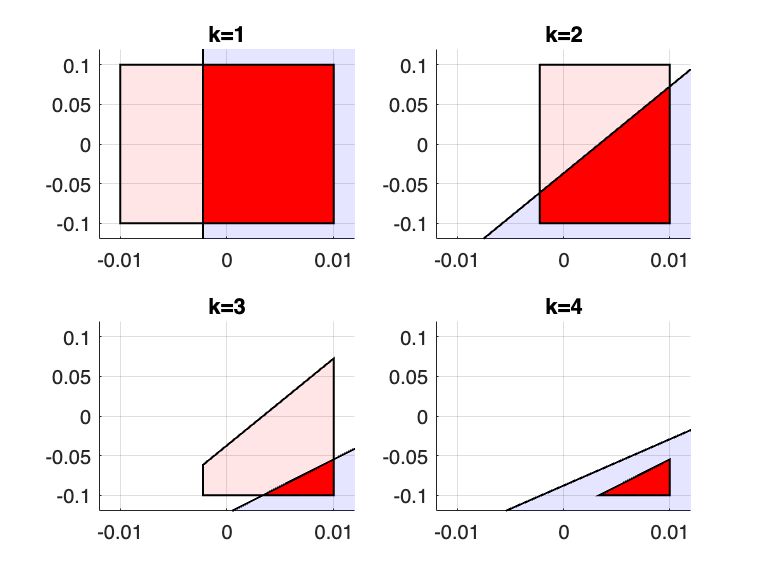

% test on first T_est time steps
T_est = 4;
for i=1:T_est
    [Omega{i+1},D{i}] = sm.update(x(:,i+1),x(:,i),u(:,i));
    if ~D{i}.isBounded 
        D{i} = Polyhedron('A',D{i}.A, 'b', D{i}.b, 'lb', -ones(2,1), 'ub', ones(2,1));
    end
    subplot(ceil(T_est/2),2,i)
    hold off
    plot(D{i},'color','b','alpha',0.1)
    hold on
    plot(Omega{i},'alpha',0.1)
    plot(Omega{i+1})
    xlim(1.2*[-h_theta(2), h_theta(1)])
    ylim(1.2*[-h_theta(4), h_theta(3)])
    title(['k=', int2str(i)])
end

### III. Performance Learning MPC

In addition to the parameter set estimates, the provided SetMembership class returns a point estimate as the center of the bounding box of the current parameter set. In this part, we want to use this point estimate to design a *performance learning MPC*.

#### MPC Formulation

Open the file `PLMPC.m` and and complete the optimization problem definition in the constructor of the performance learning MPC class. This includes the nominal state $ $z_{i+1} = A z_i + B v_i$$ w.r.t. which constraints are formulates as in the RobustMPC of Exercise 1, as well as a performance state $$x_{i+1} = A_p x_i + B_p v_i$$ w.r.t. which the objective is formulated. The matrices $$A_p$$ and $$B_p$ $are passed as parameters to the optimization problem.

*Hint: You can base this on the Robust MPC solution.*

% Complete the definition of the constructor in the performance learning MPC class: PLMPC.m

Complete the `solve` method in the `PLMPC.m` by setting the current performance matrices $A_p$ and $$B_p$$ as the current point estimates of the 

% Complete the definition of the solve method in the performance learning MPC class: PLMPC.m

% instantiate set membership estimator for PLMPC
sm_plmpc = SetMembership(Omega{1},W,ABi,AB);

% Instantiate PLMPC
plmpc = PLMPC(sys, robustMpc.N, robustMpc.Q, robustMpc.R, robustMpc.P, robustMpc.alpha,robustMpc.F,robustMpc.K,sm_plmpc);

Evalutate the performance learning MPC on the system.

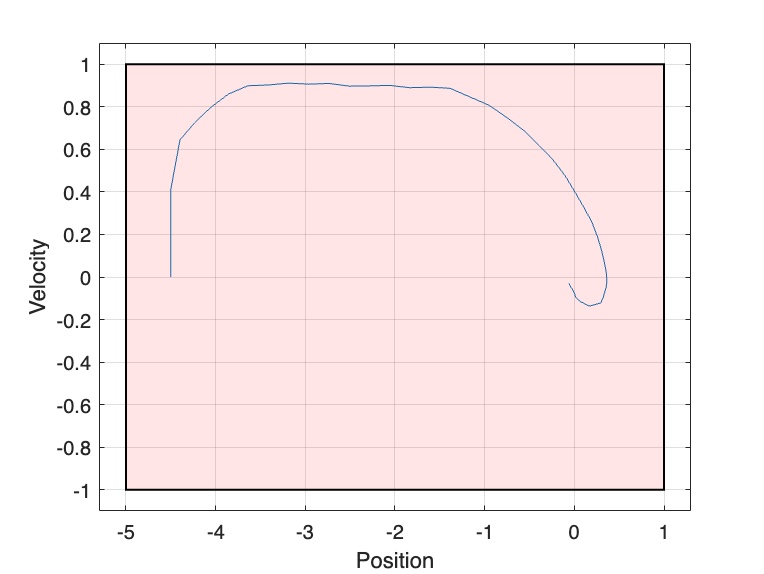

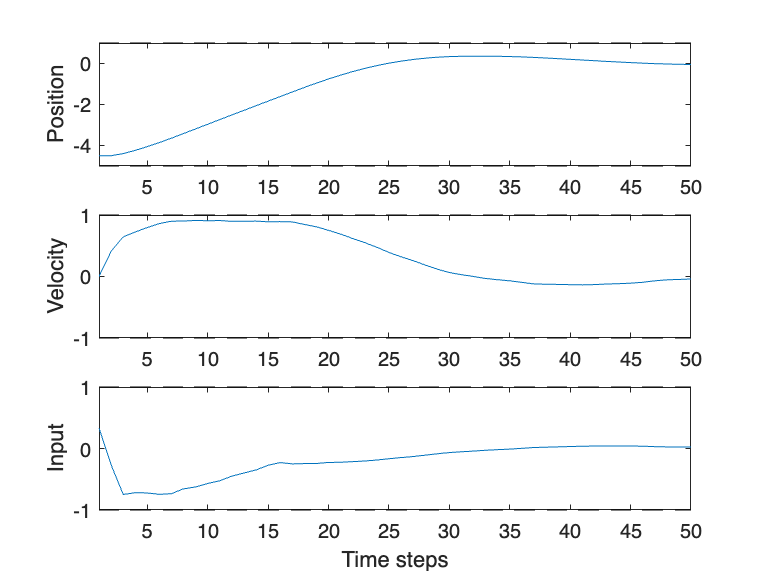

% Define controller function
pi_pl = @(x) plmpc.solve(x);

% consider additional uniform random disturbances
% w = sys.B*(rand(1,T)*2*w_max -w_max); %comment out to reuse sequence

%Simulate system
plmpc.reset(Omega{1})   % reset parameter estimate

[x, u] = SimulateMSD(sys_true,pi_pl,x_init,T,w);

% cost
J_pl = sum(sum(x.*(plmpc.Q*x))) + sum(sum(u.*(plmpc.R*u)))

% compare final A estimate
plmpc.sm.get_AB

sys.A
sys_true.A

J_pl = 258.2956

### IV. Set-Membership Adaptive Learning-Based MPC

Finally, we want to make use of the parameters set from the set-membership regression to reduce conservativeness w.r.t. the constraints. In order to do this, the open `SMMPC.m `and complete the optimization problem of the set-membership MPC class to allow for parameterized state & input constraints.

% Complete the definition of the optimization problem in SMMPC.m

ans =     1.0000    0.2500         0
   -0.0726    0.9253    0.2500


ans =     1.0000    0.2500
   -0.0750    0.9500


ans =     1.0000    0.2500
   -0.0725    0.9250


The `SetMembership` class provides a the function `estimateW_theta(X,U)` returning the set of possible model errors w.r.t. the current point estimate $\hat{\theta}_k$ and the current parameter set $\Omega_k$ 


$$ \[ \mathcal{W}^\theta_k = \left\{ w \, \Big| \, w = \phi(x,u)(\theta -\hat{\theta}_k),\  x \in \mathcal{X},\, u \in \mathcal{U},\, \theta \in \Omega \right\} \]$$


Using this function, complete the `solve `function in SMMPC.m by computing the tightened constraints according to $\mathcal{W}_k = \mathcal{W}^{\theta}_k \oplus \bar{\mathcal{W}}$ an passing it to the optimizer in each time step.

% Complete the definition of the solve function in SMMPC.m

Evaluate the resulting set membership MPC on the system

%Instantiate set membership estimator
sm_mpc = SetMembership(Omega{1},W,ABi,AB);

% Instantiate SMMPC
smMpc = SMMPC(sys, robustMpc.N, robustMpc.Q, robustMpc.R, robustMpc.P, robustMpc.alpha,robustMpc.K,sm_mpc);

% Define controller function
pi_sm = @(x) smMpc.solve(x);

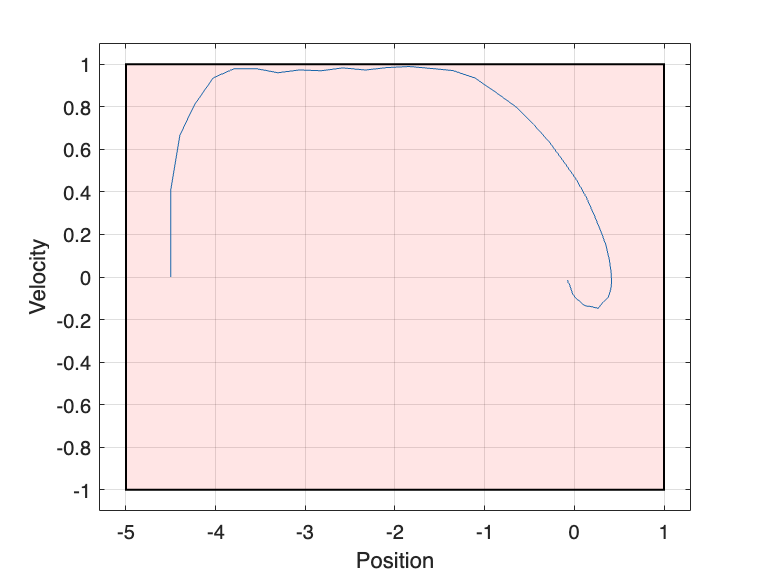

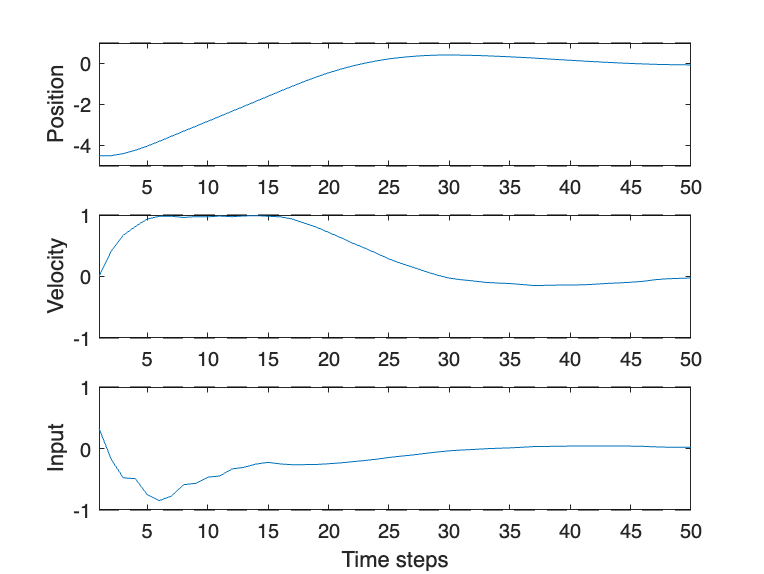

Jsm = 239.4211

% reset sm regression
sm_mpc = SetMembership(Omega{1},W,ABi,AB);

% consider additional uniform random disturbances
% w = sys.B*(rand(1,T)*2*w_max -w_max); %comment out to reuse sequence

%Simulate system
[x, u] = SimulateMSD(sys_true,pi_sm,x_init,T,w);

% cost
Jsm = sum(sum(x.*(plmpc.Q*x))) + sum(sum(u.*(plmpc.R*u)))